# Set Up

% Set up
clc;
close all;
clear;


## --- Extract EOG signals (Left and Right) ---

%% Load subject data (R1)
test = 1;  % Change this number manually to switch subject
edfFilename = sprintf('R%d_edf.mat', test);
xmlFilename = sprintf('R%d_xml.mat', test);
load(edfFilename);   % loads 'record' and 'hdr'
load(xmlFilename);   % loads 'stages', etc.

Fs = hdr.samples(3);     % Sampling frequency
epochLength = 30;        % Epoch duration in seconds

numberOfEpochs = floor(length(record(6,:)) / (Fs * epochLength)) - 1;  % Based on EOG channel

%% Extract EOG signals (Left and Right)
% Channels 6 (EOGL) and 7 (EOGR)
EOG_L = zeros(numberOfEpochs, Fs * epochLength);
EOG_R = zeros(numberOfEpochs, Fs * epochLength);

for i = 1:numberOfEpochs
    epochStart = i * Fs * epochLength;
    epochEnd = epochStart + Fs * epochLength - 1;
    EOG_L(i, :) = record(6, epochStart:epochEnd);
    EOG_R(i, :) = record(7, epochStart:epochEnd);
end


## Pre Processing

% --- Preprocess EOG (baseline removal + noise filtering) ---
[EOG_L_filt, EOG_R_filt] = preprocess_eog(EOG_L, EOG_R, Fs);


## Ploting

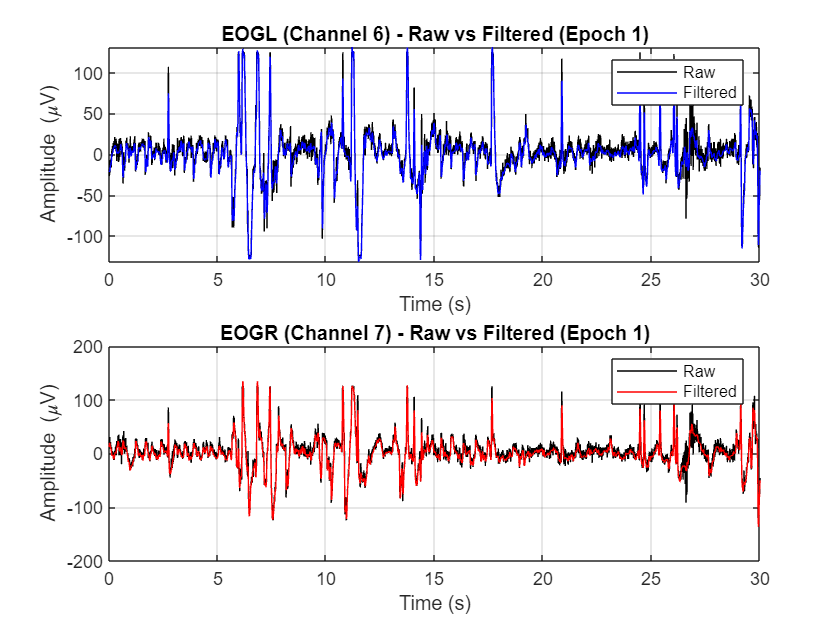

figure;

% --- EOGL (Channel 6) ---
subplot(2,1,1);
plot((1:Fs*epochLength)/Fs, EOG_L(1,:), 'k'); hold on;
plot((1:Fs*epochLength)/Fs, EOG_L_filt(1,:), 'b');
title('EOGL (Channel 6) - Raw vs Filtered (Epoch 1)');
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
legend('Raw','Filtered');
grid on;

% --- EOGR (Channel 7) ---
subplot(2,1,2);
plot((1:Fs*epochLength)/Fs, EOG_R(1,:), 'k'); hold on;
plot((1:Fs*epochLength)/Fs, EOG_R_filt(1,:), 'r');
title('EOGR (Channel 7) - Raw vs Filtered (Epoch 1)');
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
legend('Raw','Filtered');
grid on;


set(gcf, 'color', 'w');  

## **Features Extraction **

features_EOG_L=extract_EOG_features(EOG_L_filt)

features_EOG_L = struct with fields:
       blinkDetection: 178
      movementDensity: [1083×1 double]
            blinkRate: 28
    avgBlinkAmplitude: 117.1868
        avgBlinkWidth: 0.0606
            slowPower: 62.0427
             remPower: 807.0121
      ratio_RemToSlow: 13.0074


features_EOG_R=extract_EOG_features(EOG_R_filt)

features_EOG_R = struct with fields:
       blinkDetection: 172
      movementDensity: [1083×1 double]
            blinkRate: 34
    avgBlinkAmplitude: 103.4926
        avgBlinkWidth: 0.0802
            slowPower: 34.5673
             remPower: 646.8895
      ratio_RemToSlow: 18.7139
